clc, clear, close all;

# **Simulink Model Options**

% Load Simulink model
load_system('discrete_complete_model.slx');
fprintf('Simulink model loaded\n');

Simulink model loaded



wheel_corner = true; % Select for wheels in a corner, deselect for centered wheels
use_smooth = true; % Select for smooth reference, deselect for step reference
save_gif = false; % Enable/disable GIF animation creation

# **System Parameters and Inertia Calculations**

% 1. System Parameters
% CubeSat Dimensions (m)
Lx = 0.100; 
Ly = 0.100; 
Lz = 0.1135;

% Masses (kg)
m_struct = 2.0;   % Main CubeSat body
m_wheel  = 0.040; % Mass of one flywheel assembly
m_rotor_est   = m_wheel*0.6;    % EST: Spinning Rotor is 60% of total mass

% Reaction Wheel Specs
h_max = 0.6e-3;    % Momentum capacity (0.6 mNms)
rpm_max = 5600;    % Max Speed
omega_max = rpm_max * (2*pi/60); % rad/s

% Calculated Wheel Inertia
I_rw = h_max / omega_max;

% Flywheel Dimensions
% Reverse engineer radius
rw_radius = sqrt(2*I_rw/m_rotor_est); % Radius
rw_thickness = 0.0106; % Height

% 2. Coordinates of Wheel Centers (User Defined)
if wheel_corner
    % In a corner
    pos_x_input = [-0.040, -0.020, -0.020];  
    pos_y_input = [-0.020, -0.040, -0.020];      
    pos_z_input = [-0.020, -0.020, -0.040];      
else 
    % Centered on axes
    pos_x_input = [-0.040, -0.000, -0.000];  
    pos_y_input = [-0.000, -0.040, -0.000];      
    pos_z_input = [-0.000, -0.000, -0.040]; 
end

r_wheel_x = pos_x_input';
r_wheel_y = pos_y_input';
r_wheel_z = pos_z_input';

% 3. Inertia Calculations
% A. Base Structure Inertia (Hollow Box)
I_struct = diag([ ...
    (1/12)*m_struct*(Ly^2 + Lz^2), ...
    (1/12)*m_struct*(Lx^2 + Lz^2), ...
    (1/12)*m_struct*(Lx^2 + Ly^2) ]);

% B. Wheel Inertia (Cylinder)
I_spin  = 0.5 * m_rotor_est * rw_radius^2;
I_trans = (1/12) * m_rotor_est * (3*rw_radius^2 + rw_thickness^2);

% Define Local Inertia Matrices based on orientation
% X-Wheel: Spins on X axis
I_loc_x = diag([I_spin, I_trans, I_trans]);

% Y-Wheel: Spins on Y axis
I_loc_y = diag([I_trans, I_spin, I_trans]);

% Z-Wheel: Spins on Z axis
I_loc_z = diag([I_trans, I_trans, I_spin]);

% C. Parallel Axis Theorem
% Calculate the Steiner Term: m * (r^2*I - r*r')
calc_shift = @(m, r) m * [ ...
    (r(2)^2 + r(3)^2),  -(r(1)*r(2)),      -(r(1)*r(3));
    -(r(2)*r(1)),       (r(1)^2 + r(3)^2), -(r(2)*r(3));
    -(r(3)*r(1)),       -(r(3)*r(2)),      (r(1)^2 + r(2)^2) ];

% Calculate shifts based on the manual positions
J_add_x = I_loc_x + calc_shift(m_wheel, r_wheel_x);
J_add_y = I_loc_y + calc_shift(m_wheel, r_wheel_y);
J_add_z = I_loc_z + calc_shift(m_wheel, r_wheel_z);

% 4. Total Satellite Inertia
I_sat = I_struct + J_add_x + J_add_y + J_add_z;
I_sat_inv = inv(I_sat);

% 5. Actuator Dynamics
tau_motor = 0.02;  % 20ms time constant (for a small BLDC)

% EXPERIMENT: Only control one axis (activate in Simulink -> Actuators)
motor_mask = diag([1, 0, 0]);

% 6. Initial Conditions for Integrators
quat0 = [1; 0; 0; 0]; 
omega0 = [0; 0; 0];
h_rw0 = [0; 0; 0];

fprintf('System parameters loaded\n');

System parameters loaded


# **Jacobian Linearization**

% Linearization Matrices (Jacobian)
% A Matrix (6x6)
A = [
    zeros(3), 1/2*eye(3);   
    zeros(3), zeros(3)  
];

% B Matrix (6x3)
B = [
    zeros(3);       
    I_sat_inv;     
];

% C Matrix (6x6)
C = eye(6);

% D Matrix (6x3)
D = zeros(6, 3);

% Initial Conditions 
% Equilibrium: x = 0 (Zero angle, zero rate)
equilib_p = [0; 0; 0; 0; 0; 0];

fprintf('Jacobian matrix created\n');

Jacobian matrix created


# **LQI Controller Design**

% 1. System Augmentation
% Define C_phi matrix to extract attitude states (q_v) from the 6-state vector
C_qv = [eye(3), zeros(3)]; % Picks out q_v (states 1,2,3)

% Construct Augmented A matrix (9x9)
A_aug = [
        A,            zeros(6,3);  
    C_qv,           zeros(3,3)    
];

% Construct Augmented B matrix (9x3)
B_aug = [
            B;        
    zeros(3,3)  
];

% New number of states
n_aug_states = size(A_aug, 1);

% 2. LQI Gain Calculation
% State Penalties
q_max = sin(deg2rad(0.1)/2);       % Max acceptable attitude error (0.1°)
omega_max_rads     = 0.5;          % Max acceptable angular velocity (0.5 rad/s)
integral_eta_max = 0.005;          % Integral error. Smaller = stronger integral action

% Control Input Penalties
tau_c_max_Nm       = 1e-5;         % Max acceptable commanded torque

% Construct Q_aug Matrix
Q_aug = zeros(n_aug_states, n_aug_states);

% Diagonal elements for q_v (states 1-3)
Q_aug(1,1) = 1 / (q_max^2);
Q_aug(2,2) = 1 / (q_max^2);
Q_aug(3,3) = 1 / (q_max^2);

% Diagonal elements for omega (states 4-6)
Q_aug(4,4) = 1 / (omega_max_rads^2);
Q_aug(5,5) = 1 / (omega_max_rads^2);
Q_aug(6,6) = 1 / (omega_max_rads^2);

% Diagonal elements for integral_eta (states 10-12)
Q_aug(7,7) = 1 / (integral_eta_max^2);
Q_aug(8,8) = 1 / (integral_eta_max^2);
Q_aug(9,9) = 1 / (integral_eta_max^2);

% Construct R_lqi Matrix
R_lqi = zeros(3,3);

% Diagonal elements for control torques (inputs 1-3)
R_lqi(1,1) = 1 / (tau_c_max_Nm^2);
R_lqi(2,2) = 1 / (tau_c_max_Nm^2);
R_lqi(3,3) = 1 / (tau_c_max_Nm^2);

% Calculate the LQI Gain Matrix
[K_lqi, S_lqi, P_lqi] = lqr(A_aug, B_aug, Q_aug, R_lqi);

K_q     = K_lqi(:, 1:3);  
K_omega = K_lqi(:, 4:6);  
K_I     = K_lqi(:, 7:9);

fprintf('LQI Gain Matrix calculated\n');

LQI Gain Matrix calculated


## **Anti-Windup**

K_aw = inv(K_I);

## **Discrete LQI**

% Sample Time
dt = 0.01; % 100 Hz

% 1. Discretize the plant matrices
sys_cont = ss(A_aug, B_aug, eye(9), zeros(9,3));
sys_disc = c2d(sys_cont, dt, 'zoh');
Ad_aug = sys_disc.A;
Bd_aug = sys_disc.B;

% 2. Calculate Discrete LQR Gains (DLQR)
[K_dlqi, S_dlqi, P_dlqi] = dlqr(Ad_aug, Bd_aug, Q_aug, R_lqi);

K_dq     = K_dlqi(:, 1:3);  
K_domega = K_dlqi(:, 4:6);  
K_dI     = K_dlqi(:, 7:9);

disp('Discrete LQI Gain Matrix calculated');

Discrete LQI Gain Matrix calculated


## **Discrete Anti-Windup**

K_daw = inv(K_dI);

# **Sensor Suite**

% 1. ADCS
% The ADCS fuses Sun, Mag, and Gyro to output attitude .
adcs_sample_time = 0.01; % 10 ms

% RPE (Jitter/Noise). Spec: 0.0028 deg @ 1-sigma
adcs_rpe_rad = deg2rad(0.0028);
% Power = sigma^2 * sample_time
adcs_noise_power = adcs_rpe_rad^2 * adcs_sample_time; 

% APE (Absolute Bias). Spec: 1.0 deg @ 1-sigma
adcs_ape_rad = deg2rad(1.0);

% 2. MEMS Gyroscope (Rate Feedback).
% Based on Bosch BMI088 / Standard MEMS.
gyro_sample_time = 0.01; % 100 Hz

% Rate Noise (Spectral Density). Spec: 0.007 deg/s/sqrt(Hz)
gyro_arw_rad = deg2rad(0.007);
% Power = ARW^2
gyro_noise_power = gyro_arw_rad^2; 

% Bias Instability. Spec: 10 deg/hr
gyro_bias_instability_rad_s = deg2rad(10/3600);
gyro_walk_power = gyro_bias_instability_rad_s^2 * gyro_sample_time;

% 3. Hall Sensors (Actuator Feedback)
% Based on Maxon EC45 Flat / CubeSpace Wheels.
rw_sample_time = 0.01; % 100 Hz (aligned with ADCS)

% Speed Jitter (Noise). Spec: +/- 2 RPM stability -> @ 3-sigma
rw_jitter_rads = 2.0/3.0 * (2*pi)/60;
% Noise
rw_noise_power = rw_jitter_rads^2 * rw_sample_time;

% Speed Resolution (Quantization). Spec: 0.5 RPM steps
rw_quantization_interval = 0.5 * (2*pi)/60;

fprintf('Sensor parameters loaded\n');

Sensor parameters loaded


# **Kalman Filter**

% 1. Measurement Noise Covariance (R_noise) - Higher = Trust sensors less
R_q_val = adcs_rpe_rad^2;                           % ADCS 
R_w_val = (gyro_arw_rad^2)*(1/gyro_sample_time);    % Gyros
R_h_val = rw_jitter_rads^2;                         % Hall sensor

% Build R Matrix
R_diag_val = [repmat(R_q_val, 1, 4), ...
              repmat(R_w_val, 1, 3), ...
              repmat(R_h_val, 1, 3)];
R_noise = diag(R_diag_val);

% 2. Process Noise Covariance (Q_noise) - Lower = Trust model more
Q_q_val = (sqrt(R_w_val) * adcs_sample_time)^2;     % Kinematics (Trust high)
Q_w_val = 1e-4;                                     % Dynamics (Trust low due to saturation)
Q_h_val = 1e-5;                                     % Momentum (Trust low due to saturation)

% Build Q Matrix
Q_diag_val = [repmat(Q_q_val, 1, 4), ...
              repmat(Q_w_val, 1, 3), ...
              repmat(Q_h_val, 1, 3)];
Q_noise = diag(Q_diag_val);

fprintf('EKF ready\n');

EKF ready


# **Trajectory and Disturbance Selection**

% 1. REFERENCE
% Step Reference (degree) (successive steps are relative to the previous step)
% Step 1
ini_step1 = [0, 0, 0];
end_step1 = [150, 0, 0];
t_step1 = 5; % Moment of step (s)

% Step 2
ini_step2 = [0, 0, 0];
end_step2 = [0, 0, 0];
t_step2 = 20; % Moment of step (s)

% Step 3
ini_step3 = [0, 0, 0];
end_step3 = [0, 0, 0];
t_step3 = 40; % Moment of step (s)

% Smooth Reference Trajectory (degree)
start_time = 0;
end_time = 30;
ini_value = [0, 0, 0];
end_value = [360, 30, 0];

% Trajectory type
if use_smooth
    set_param('discrete_complete_model/Reference/Reference Selector', 'sw', '1');  % bottom input
else
    set_param('discrete_complete_model/Reference/Reference Selector', 'sw', '0');  % top input
end

fprintf('Trajectory calculated\n');

Trajectory calculated



% 2. DISTURBANCE
% Disturbance 1
% Typical values range from 1e-3 Nm to 4e-2 Nm for 0.01s duration
disturb_force1 = [0, -2e-2, 1.21e-2];
d_disturb1 = 0.01; % Duration of impact (s)
t_disturb1 = 20; % Moment of impact (s)

% Disturbance 2
% Typical values range from 1e-5 Nm to 6e-4 Nm for 2s duration
disturb_force2 = [0, 0, 0];
d_distub2 = 2; % Duration of impact (s)
t_disturb2 = 50; % Moment of impact (s)

% Constant disturbance
% Typical values range from 1e-6 Nm to 1e-9 Nm
disturb_const = [0, 0, 0e-6]; 

fprintf('Disturbance loaded\n');

Disturbance loaded


# **Run Simulation**

sim_duration = 100;   % Simulation duration (s)

set_param('discrete_complete_model', 'StopTime', num2str(sim_duration));
out = sim("discrete_complete_model.slx");

fprintf('Simulation completed\n');

Simulation completed


# **Animation**

if save_gif
    disp("GIF saving enabled");
end

speed_factor = 20; % Animation speed (lower if too fast)
alpha = 1; % Transparency of the satellite (0.2 or 1)

run("animation.m");

Pre-computing transformations...
Starting animation...
Total frames: 501
Animation finished


# **Plots for Attitude, Wheel Speed and Control Torque**

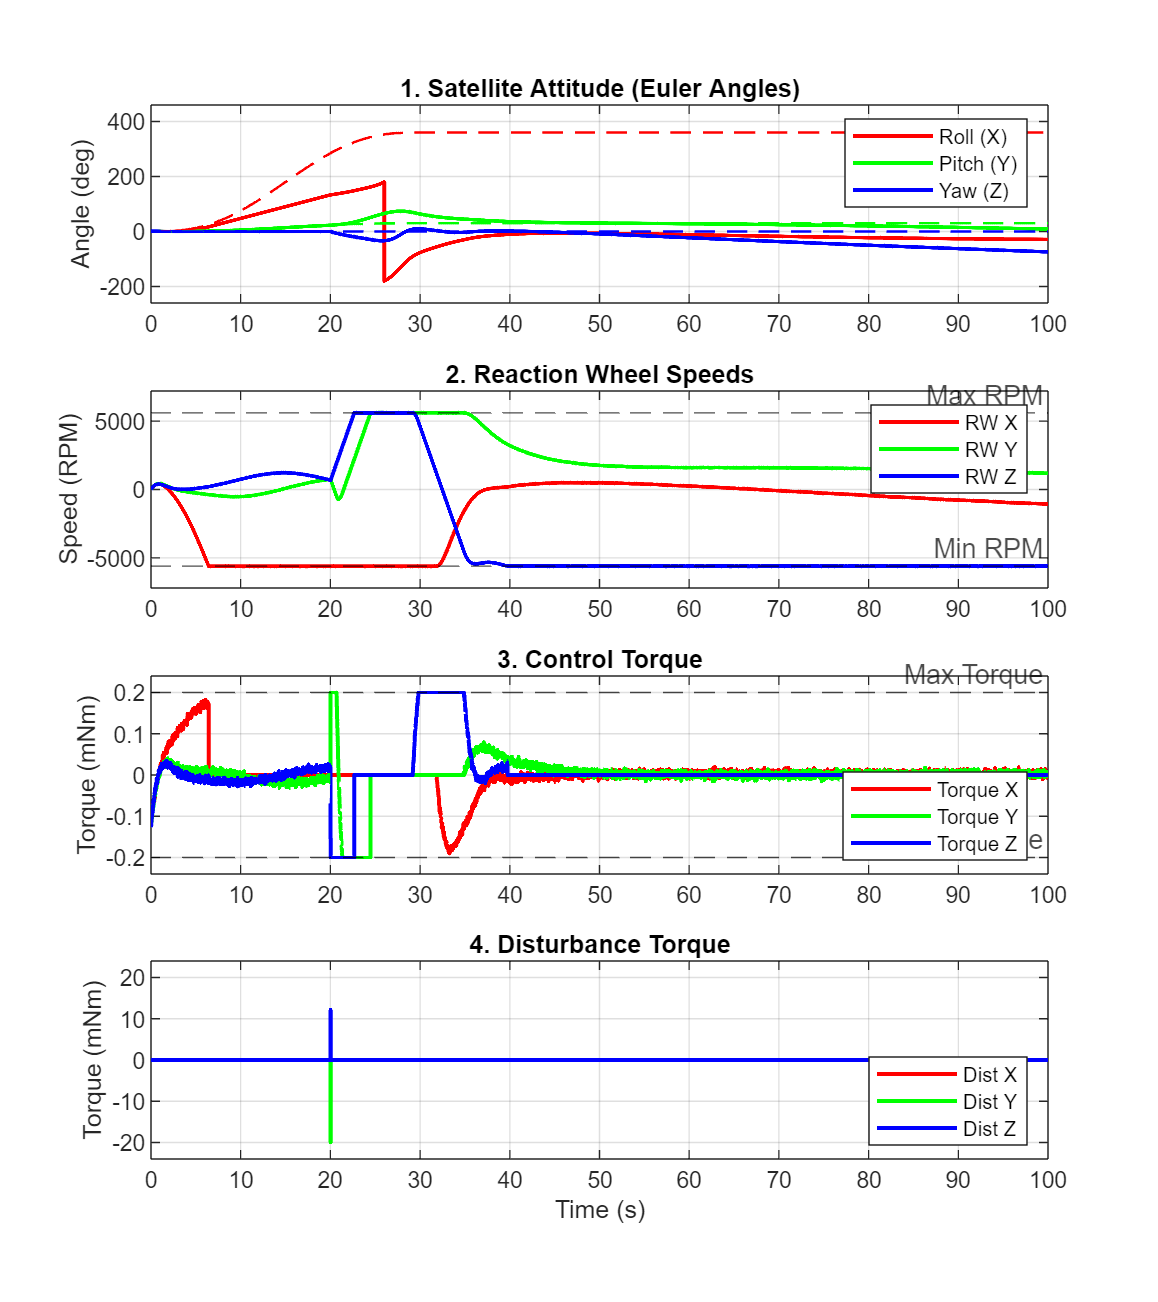

% Extract Reference and External Disturbances
t_ref = out.ref.Time;
ref_data = out.ref.Data;

t_dist = out.T_ext.Time;
dist_data = out.T_ext.Data;

% Extract Angles
t_angles = out.angles.Time;       
angles_data = out.angles.Data; 

roll_deg  = rad2deg(angles_data(:,3)); 
pitch_deg = rad2deg(angles_data(:,2)); 
yaw_deg   = rad2deg(angles_data(:,1)); 

% Extract Wheel Speeds
t_omegarw = out.omega_rw.Time;     

omega_rw_rads = out.omega_rw.Data;
omega_rw_rpm  = omega_rw_rads * (60/(2*pi));

% Extract Control Torque
t_tau = out.tau_c.Time;              
tau_data = out.tau_c.Data; 

% Plots
figure('Position', [0 0 800 900]); % [left  bottom  width  height]

% Attitude
subplot(4,1,1);
plot(t_angles, roll_deg, 'r', 'LineWidth', 1.5); hold on;
plot(t_angles, pitch_deg, 'g', 'LineWidth', 1.5);
plot(t_angles, yaw_deg, 'b', 'LineWidth', 1.5);
plot(t_ref, ref_data(:,1), 'r--', 'LineWidth', 1);
plot(t_ref, ref_data(:,2), 'g--', 'LineWidth', 1);
plot(t_ref, ref_data(:,3), 'b--', 'LineWidth', 1);
ylabel('Angle (deg)');
title('1. Satellite Attitude (Euler Angles)');
legend('Roll (X)', 'Pitch (Y)', 'Yaw (Z)', 'Location','northeast');
grid on;

yl = ylim;
padding = 0.1 * (yl(2) - yl(1));  % 5% padding
ylim([yl(1) - padding, yl(2) + padding]);

% Wheel Speeds
subplot(4,1,2);
plot(t_omegarw, omega_rw_rpm(:,1), 'r', 'LineWidth', 1.5); hold on;
plot(t_omegarw, omega_rw_rpm(:,2), 'g', 'LineWidth', 1.5);
plot(t_omegarw, omega_rw_rpm(:,3), 'b', 'LineWidth', 1.5);
ylabel('Speed (RPM)');
yline(5600, 'k--', 'Max RPM');
yline(-5600, 'k--', 'Min RPM');
title('2. Reaction Wheel Speeds');
legend('RW X', 'RW Y', 'RW Z', 'Location','northeast');
grid on;

yl = ylim;
padding = 0.1 * (yl(2) - yl(1));  % 5% padding
ylim([yl(1) - padding, yl(2) + padding]);

% Control Torque
subplot(4,1,3);
plot(t_tau, tau_data(:,1)*1000, 'r', 'LineWidth', 1.5); hold on;
plot(t_tau, tau_data(:,2)*1000, 'g', 'LineWidth', 1.5);
plot(t_tau, tau_data(:,3)*1000, 'b', 'LineWidth', 1.5);
ylabel('Torque (mNm)');
yline(0.2, 'k--', 'Max Torque');
yline(-0.2, 'k--', 'Min Torque');
title('3. Control Torque');
legend('Torque X', 'Torque Y', 'Torque Z', 'Location','southeast');
grid on;

yl = ylim;
padding = 0.1 * (yl(2) - yl(1));  % 5% padding
ylim([yl(1) - padding, yl(2) + padding]);

% Disturbance Torque
subplot(4,1,4);
plot(t_dist, dist_data(:,1)*1000, 'Color', 'r', 'LineWidth', 1.5); hold on;
plot(t_dist, dist_data(:,2)*1000, 'Color', 'g', 'LineWidth', 1.5);
plot(t_dist, dist_data(:,3)*1000, 'Color', 'b', 'LineWidth', 1.5);
ylabel('Torque (mNm)');
xlabel('Time (s)');
title('4. Disturbance Torque');
legend('Dist X', 'Dist Y', 'Dist Z', 'Location','southeast');
grid on;

yl = ylim;
padding = 0.1 * (yl(2) - yl(1));  % 5% padding
ylim([yl(1) - padding, yl(2) + padding]);

# **Controllability and Observability**

% Number of states
n_states = size(A, 1);

% 1. Controllability Analysis
rank_C = rank(ctrb(A, B));
if rank_C == n_states
    fprintf('The system is CONTROLLABLE (rank = %d of %d)\n', rank_C, n_states);
else
    fprintf('The system is NOT controllable (rank = %d of %d)\n', rank_C, n_states);
end

% 2. Observability Analysis
rank_O = rank(obsv(A, C));

if rank_O == n_states
    fprintf('The system is OBSERVABLE (rank = %d of %d)\n', rank_O, n_states);
else
    fprintf('The system is NOT observable (rank = %d of %d)\n', rank_O, n_states);
end

# **Pole-Zero Map**

% 1. Eigenvalues (Poles)
poles_OL = eig(A);      % Open-Loop Poles (Plant without controller)
poles_CL = P_lqi;       % Closed-Loop Poles (Plant + LQI Controller)

% 2. Plot
figure; hold on; grid on; axis equal;
xlabel('Real'); ylabel('Imaginary');
title('Pole Placement');

% Plot poles
plot(real(poles_OL), imag(poles_OL), 'bx', 'MarkerSize', 10, 'LineWidth', 1);
plot(real(poles_CL), imag(poles_CL), 'ro', 'MarkerSize', 10, 'LineWidth', 1);

% Axes
xline(0, 'k');      % imaginary axis
yline(0, 'k');      % real axis
legend('Open-Loop Poles (Plant)', 'Closed-Loop Poles (+LQI)', 'Location', 'best');